# Wisconsin Breast Cancer Database

Performs outlier detection on the breast cancer databases from the University of Wisconsin Hospitals, Madison from Dr. William H. Wolberg.

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

opts = delimitedTextImportOptions("NumVariables", 11);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["SampleCodeNumber", "ClumpThickness", "UniformityOfCellSize", ...
    "UniformityOfCellShape", "MarginalAdhesion", "SingleEpithelialCellSize", ...
    "BareNuclei", "BlandChromatin", "NormalNucleoli", "Mitoses", "Class"];
opts.VariableTypes = ["int32", "double", "double", ...
    "double", "double", "double", ...
    "double", "double", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

opts.ImportErrorRule = "omitrow";

% Import the data
rawData = readtable("./datasets/breast-cancer-wisconsin/breast-cancer-wisconsin.data", opts);

% convert Class to category
rawData.Class = renamecats(rawData.Class, {'benign', 'malignant'});

clear opts;

rawData(1:8, :)

ans = 8×11 table
    SampleCodeNumber    ClumpThickness    UniformityOfCellSize    UniformityOfCellShape    MarginalAdhesion    SingleEpithelialCellSize    BareNuclei    BlandChromatin    NormalNucleoli    Mitoses      Class  
    ________________    ______________    ____________________    _____________________    ________________    ________________________    __________    ______________    ______________    _______    _________

        1000025               5                     1                       1                     1                       2                     1              3                 1          

groupcounts(rawData, "Class")

ans = 2×3 table
      Class      GroupCount    Percent
    _________    __________    _______

    benign          444        65.007 
    malignant       239        34.993 


## Preperation

Similar to Hawkins et al.[1] we drop every 6th entry of the "malignant" class to form a very unbalanced distribution.

numMalignantSamples = sum(rawData.Class == "malignant");

contamination =239;
benignIndices = find(rawData.Class == "benign");

malignantIndices = find(rawData.Class == "malignant");
malignantSampleIndices = datasample(malignantIndices, contamination, "Replace", false);
rawData(head(malignantSampleIndices), :)

ans = 8×11 table
    SampleCodeNumber    ClumpThickness    UniformityOfCellSize    UniformityOfCellShape    MarginalAdhesion    SingleEpithelialCellSize    BareNuclei    BlandChromatin    NormalNucleoli    Mitoses      Class  
    ________________    ______________    ____________________    _____________________    ________________    ________________________    __________    ______________    ______________    _______    _________

        1211202                7                    5                      10                     10                      10                   10              4                 10         

data = rawData(sort(cat(1, benignIndices, malignantSampleIndices)),:);

clear malignantIndices;
clear benignIndices;
clear malignantSampleIndices;

groupcounts(data, "Class")

ans = 2×3 table
      Class      GroupCount    Percent
    _________    __________    _______

    benign          444        65.007 
    malignant       239        34.993 


unlabeledData = table2array(removevars(data,{'SampleCodeNumber', 'Class'}));

[1] Hawkins, S., He, H., Williams, G., Baxter, R. (2002). Outlier Detection Using Replicator Neural Networks. In: Kambayashi, Y., Winiwarter, W., Arikawa, M. (eds) Data Warehousing and Knowledge Discovery. DaWaK 2002. Lecture Notes in Computer Science, vol 2454. Springer, Berlin, Heidelberg. [https://doi.org/10.1007/3-540-46145-0_17](https://doi.org/10.1007/3-540-46145-0_17)

## Computation

alpha = 0.5;
x = rZscores(unlabeledData);
kModel = AutoRbfKernel(x);

AutoRbfKernel: Sigma = 9.40382301227245


poc = kMRCD(kModel); 
solution = poc.runAlgorithm(x, alpha);

Convergence at iteration 5, SDO
Convergence at iteration 7, SpatialRank
Convergence at iteration 3, SpatialMedian
Convergence at iteration 6, SSCM
-> Best estimator is SpatialMedian


## Evaluation

outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "Class")


ans =

  0×3 empty table



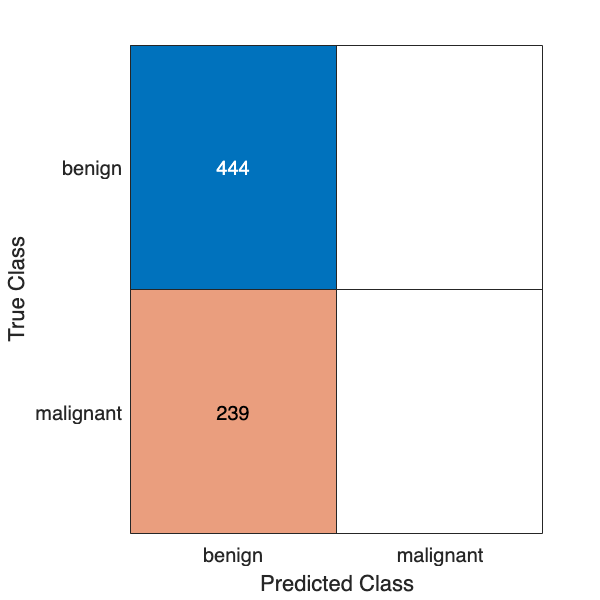

grouphat = categorical(repmat("benign", [size(data,1),1]), categories(data.Class));
grouphat(solution.flaggedOutlierIndices) = "malignant";

figure(1);
cm = confusionchart(data.Class,grouphat);
set(gcf,'Position',[100, 100, 300, 300]);

true_negatives = cm.NormalizedValues(1,1);
false_negatives = cm.NormalizedValues(2,1);

true_positives = cm.NormalizedValues(2,2);
false_positves = cm.NormalizedValues(1,2);

accuracy = (true_positives + true_negatives)/size(data, 1);
precision = true_positives / (true_positives + false_positves);
sensitivity = true_positives / (true_positives + false_negatives);
specificity = true_negatives / (true_negatives + false_positves);

table(accuracy, precision, sensitivity, specificity)

ans = 1×4 table
    accuracy    precision    sensitivity    specificity
    ________    _________    ___________    ___________

    0.65007        NaN            0              1     


hSubsetRelativeSize = 0.5:0.05:1;
objectiveValues = zeros(size(hSubsetRelativeSize));
for i=1:numel(hSubsetRelativeSize)
    objectiveValues(i) = poc.runAlgorithm(x, hSubsetRelativeSize(i)).obj;
end

Convergence at iteration 7, SDO
Convergence at iteration 7, SpatialRank
Convergence at iteration 3, SpatialMedian
Convergence at iteration 6, SSCM
-> Best estimator is SpatialMedian
Convergence at iteration 3, SDO
Convergence at iteration 3, SpatialRank
Convergence at iteration 2, SpatialMedian
Convergence at iteration 4, SSCM
-> Best estimator is SDO
Convergence at iteration 3, SDO
Convergence at iteration 5, SpatialRank
Convergence at iteration 3, SpatialMedian
Convergence at iteration 5, SSCM
-> Best estimator is SpatialMedian
Convergence at iteration 5, SDO
Convergence at iteration 5, SpatialRank
Convergence at iteration 2, SpatialMedian
Convergence at iteration 5, SSCM
-> Best estimator is SpatialMedian
Convergence at iteration 6, SDO
Convergence at iteration 7, SpatialRank
Convergence at iteration 4, SpatialMedian
Convergence at iteration 4, SSCM
-> Best estimator is SDO
Convergence at iteration 5, SDO
Convergence at iteration 6, SpatialRank
Convergence at iteration 7, SpatialMed

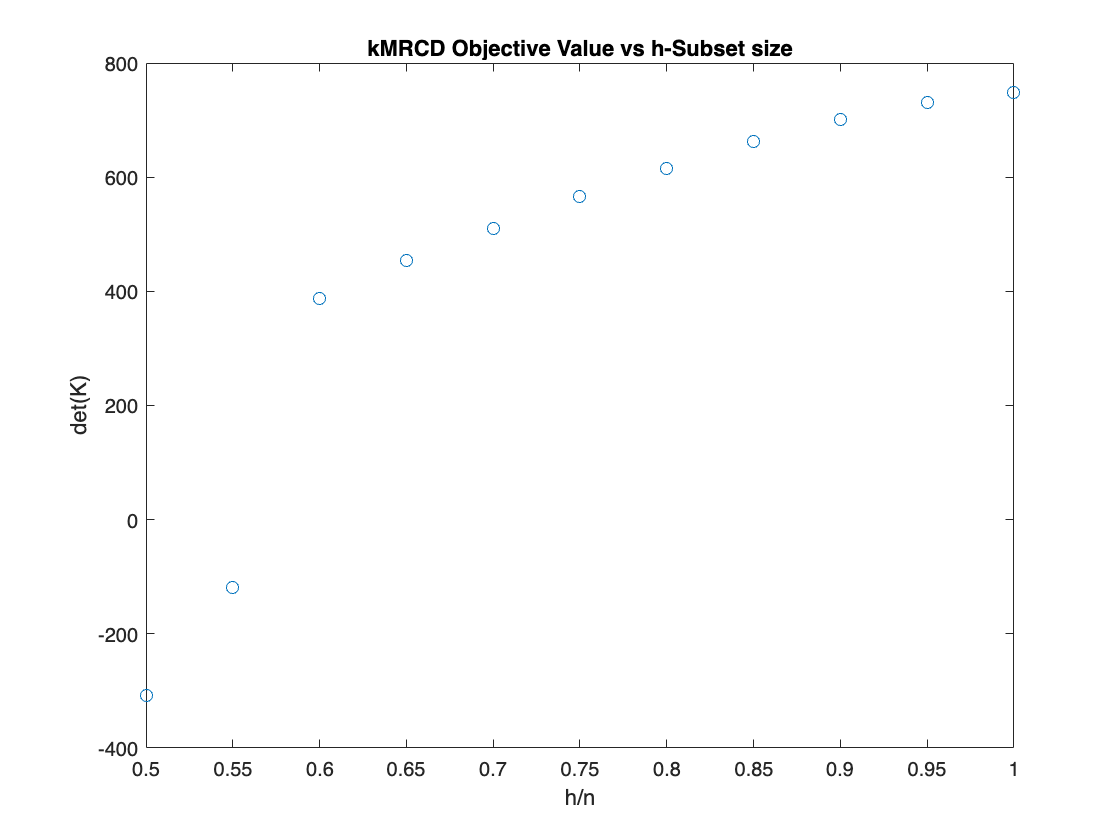

figure(2);
plot(hSubsetRelativeSize, objectiveValues, 'o')
title('kMRCD Objective Value vs h-Subset size')
xlabel('h/n')
ylabel('det(K)')